Here I'll use a dual stage (DISO) model of a HDD and look at how changes in the reference trajectory affect the results.

Controller Design

Warning:  A lot of detail here.  I'm setting up and solving an $H_\infty$ optimal control problem just to get a controller.  This is from another class...just treat as black magic :).

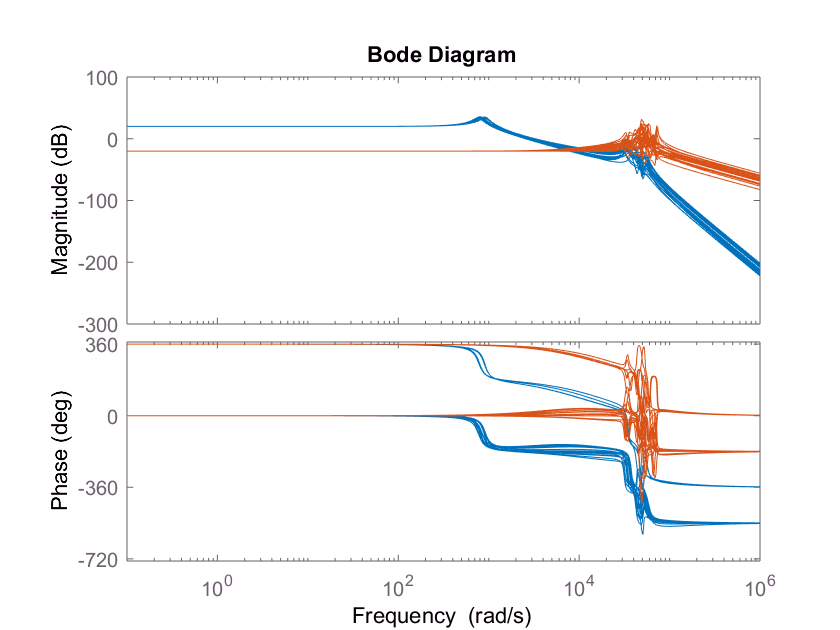

HDDModel_DS_Uncertain;
Gv = VCM.NominalValue;
Gp = PZT.NominalValue;
bode(VCM,PZT)

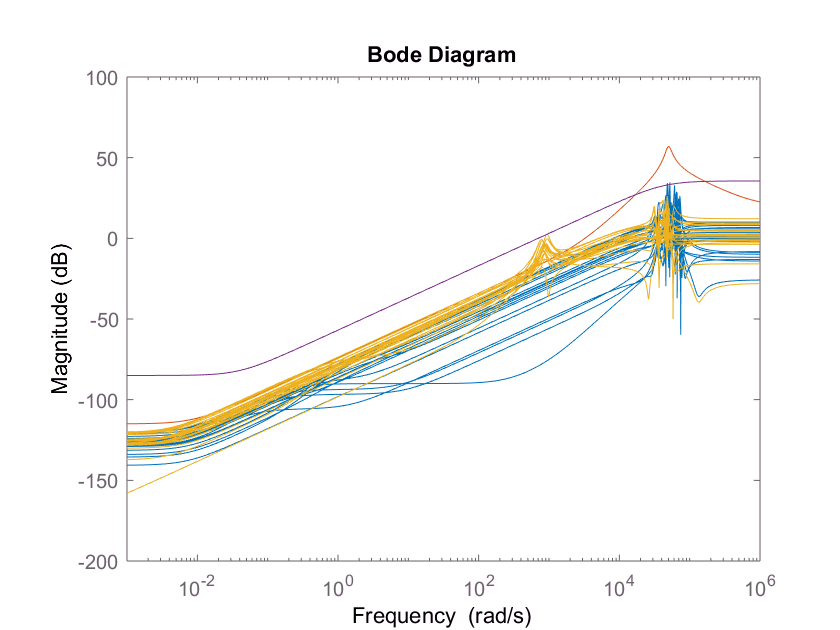

Gp_samples = usample(PZT,20);
W_D2 = makeweight(10^(-115/20),5000,10)*notch(-40,900000,50000);  %Played with this a bit
Up = ultidyn('Up',[1,1]);
Pp = PZT.NominalValue*(1+W_D2*Up);
Gv_samples = usample(VCM,20);
W_D1 = makeweight(10^(-85/20),700,60);  %Played with this a bit.
Uv = ultidyn('Uv',[1,1]);
Pv = VCM.NominalValue*(1+W_D1*Uv);
%Check fit
bodemag((Gp_samples-Gp)/Gp,W_D2,(Gv_samples-Gv)/Gv,W_D1,{0.001,1000000});

Now I'll build a performance weight and actuation penalty weights.

Wp = makeweight(100,1000,1/3);  %Simple 1st order weight
Wu_1 = 1/100000;  %Very little weight on VCM - practically unlimited stroke
Wu_2 = makeweight(100,500,1/1000);  %High penalty at low frequency for PZT

For the disturbance model, I'll include a couple of the flexible structure modes of the disk.

Gd = notch(-10,50,800)*notch(-6,100,1100);  %A couple of localized resonances

Now I can build the full generalized plant for $H_\infty$ synthesis.

systemnames = 'Gv Gp Gd Wu_1 Wu_2 W_D1 W_D2 Wp';
inputvar = '[ud1;ud2;d;u1;u2]';
outputvar = '[W_D1;W_D2;Wp;Wu_1;Wu_2;-Gv-Gp-Gd]';
input_to_Gv = '[u1+ud1]';
input_to_Gp = '[u2+ud2]';
input_to_Gd = '[d]';
input_to_Wu_1 = '[u1]';
input_to_Wu_2 = '[u2]';
input_to_W_D1 = '[u1]';
input_to_W_D2 = '[u2]';
input_to_Wp = '[Gv+Gp+Gd]';
cleanupsysic = 'yes';  %This drops all the useless variables from workspace
P = sysic;

Let's now solve the standard problem to get the controller.

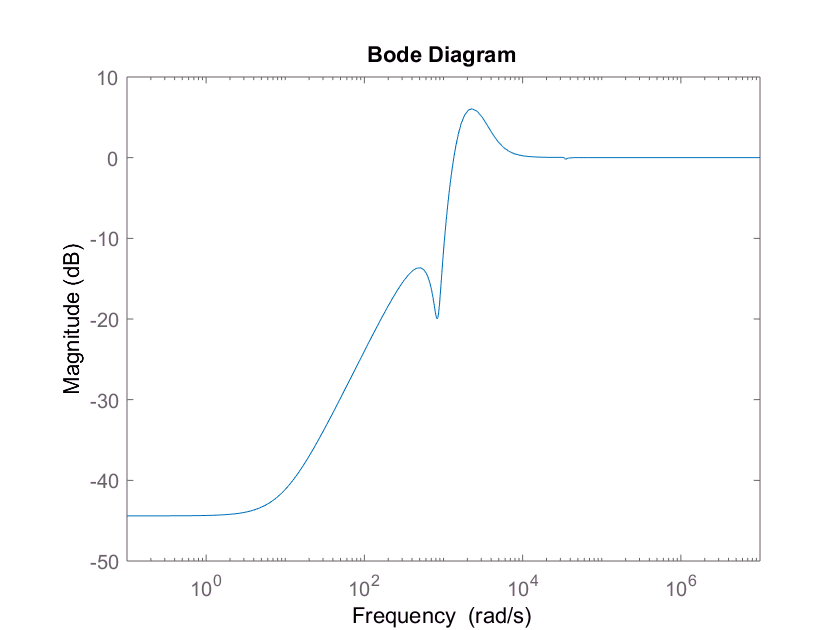

[Kinf,CLinf,GAMinf] = hinfsyn(P,1,2);
S = 1-feedback([Gv Gp]*Kinf,1);  %The "sensitivity" function
bodemag(S)

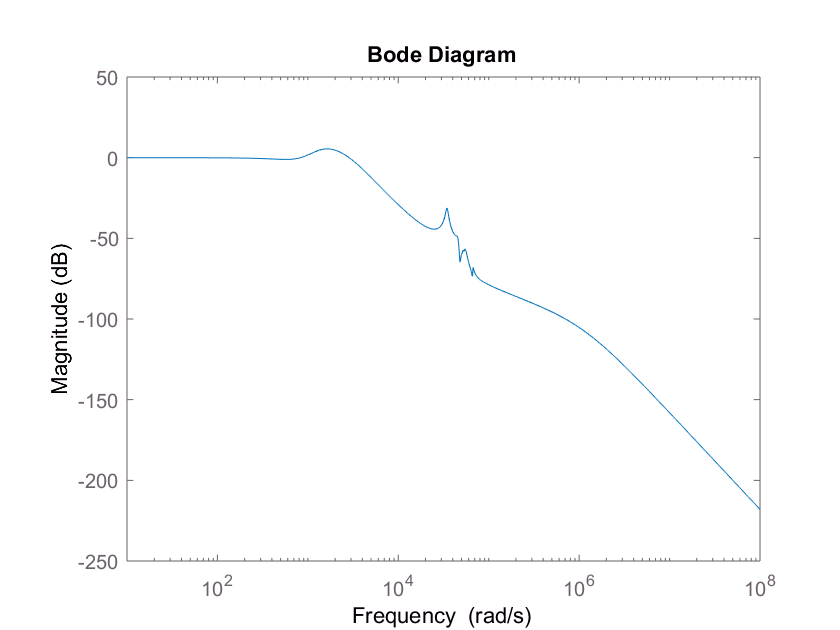

bodemag(1-S)  %The closed loop transfer function

With the control design unpleasantness out of the way, let's segue to creating a minimum jerk trajectory.

tfinal = 10e-3;  %Arrive in 10 ms
t = [0:.00001:tfinal];
x = 10*(t/tfinal).^3-15*(t/tfinal).^4+6*(t/tfinal).^5;
minjerk= [t' x'];

Let's now compare that to another very popular profile - the trapezoidal (constant velocity) approach.

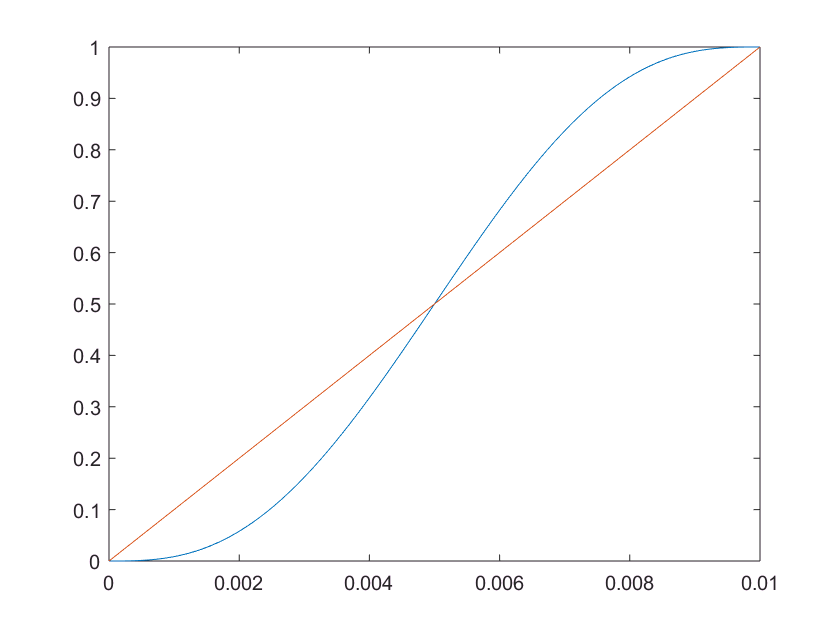

xtrap = t/tfinal;
trap_profile = [t',xtrap'];
plot(t,x,t,xtrap)

Now let's compare performance between these trajectories starting from rest.

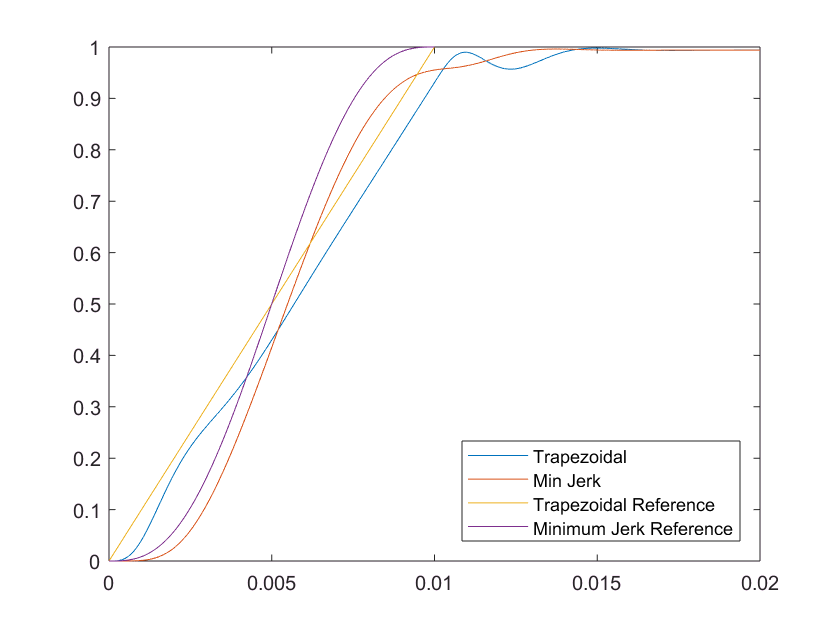


sim('HDD_MinJerk');
plot(position(:,1),[position(:,2),position(:,3)], t, [xtrap' x']);
legend('Trapezoidal','Min Jerk','Trapezoidal Reference', 'Minimum Jerk Reference','Location','southeast')

Now let's look at control usage.

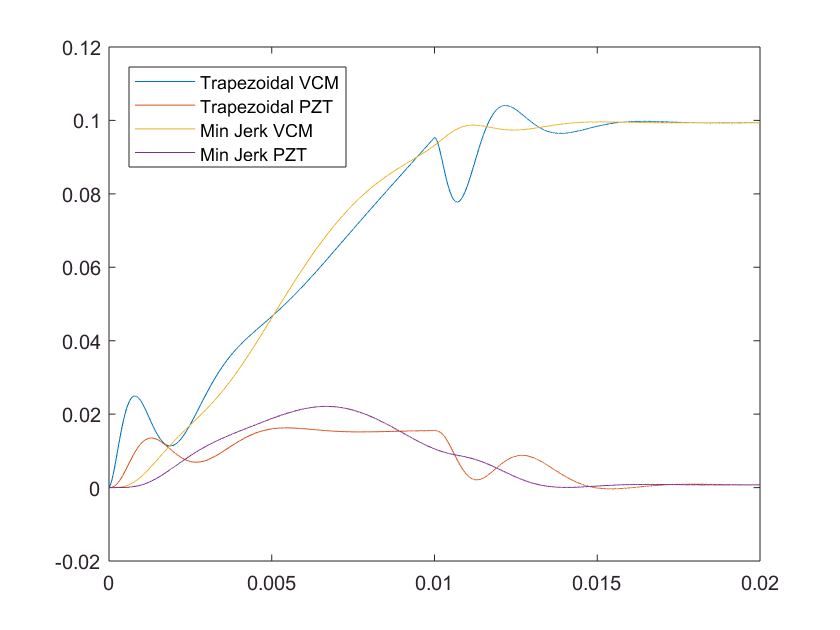

plot(control(:,1),control(:,2:end));
legend('Trapezoidal VCM','Trapezoidal PZT','Min Jerk VCM','Min Jerk PZT','Location','northwest')

Why not just use a step???

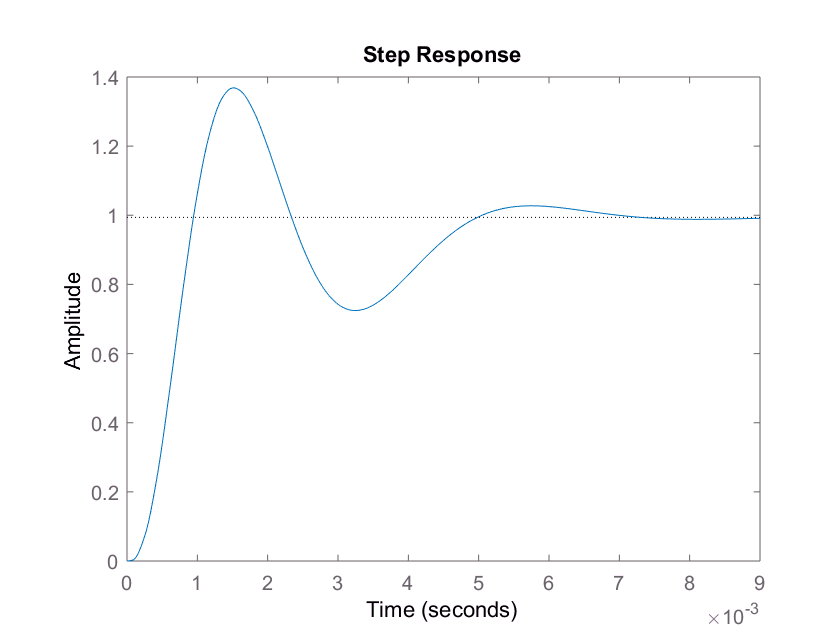

step(1-S)

A little wobbly, but I can probably input shape it.  What about the control?  Here's the real issue...

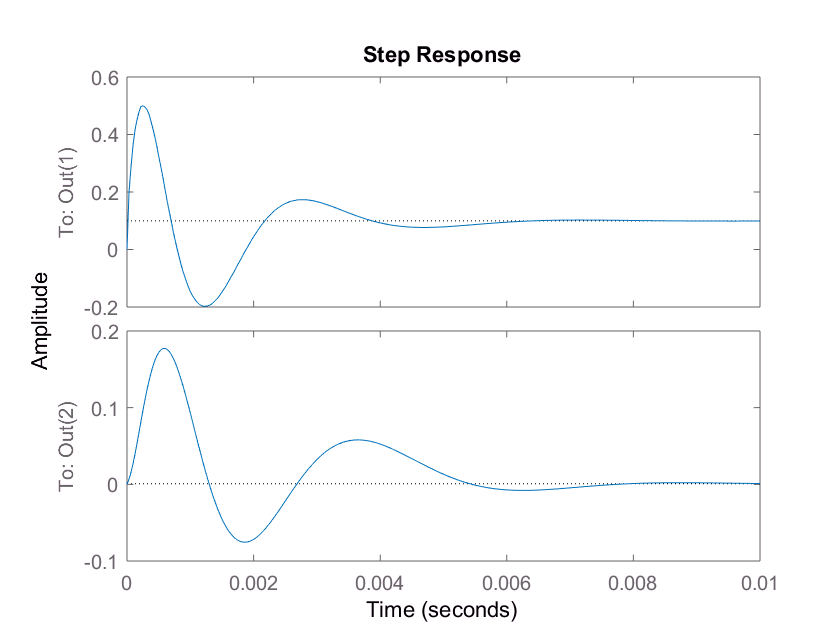

R = inv(eye(2)+Kinf*[Gv Gp])*Kinf;  %Transfer function from reference to control
step(R)

Basically, I need to accept that I can't get there this fast due to saturation, and be sensible about the profile I choose to follow.  In particular, the high-frequency components of the step are making my PZT work ~10x as hard.